% Punto 1

I = imread("coins.png");
whos("I");

  Name        Size             Bytes  Class    Attributes

  I         246x300            73800  uint8              




% tamaño en bytes
% 73800
% numero de pixeles
% 246x300
% numero de bits por pixel
% 8 bits

%imwrite(I, "coins.png");
%imwrite(I, "coins.jpg");
%imwrite(I, "coins5.jpg", "Quality", 5);

coins0 = imread("coins.png");
whos("coins");
coins1 = imread("coins.jpg");

Error using imread>get_full_filename
File "coins.jpg" does not exist.

Error in imread (line 371)
    fullname = get_full_filename(filename);

whos("coins1");
coins2 = imread("coins5.jpg");
whos("coins2");

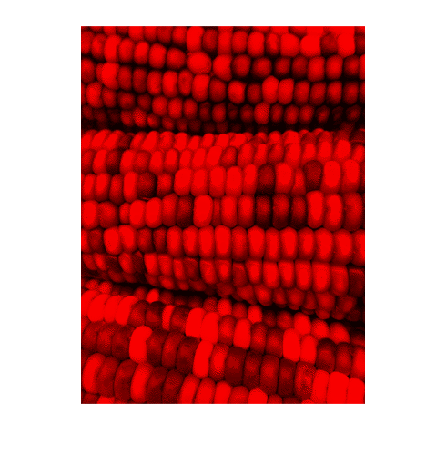

% Punto 2.1

[I, map] = imread("corn.tif");
%imwrite(I,map,"corn.png");
r = zeros(256,3);
g = zeros(256,3);
b = zeros(256,3);

r(:,1) = map(:,1);
g(:,2) = map(:,2);
b(:,3) = map(:,3);

%imwrite(I,r,"redCorn.png")
imshow(I,r);

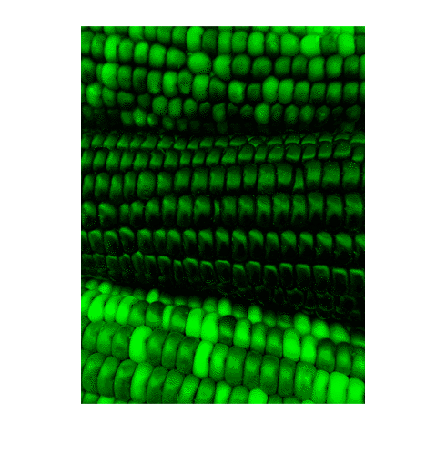

%imwrite(I,g,"greenCorn.png")
imshow(I,g);

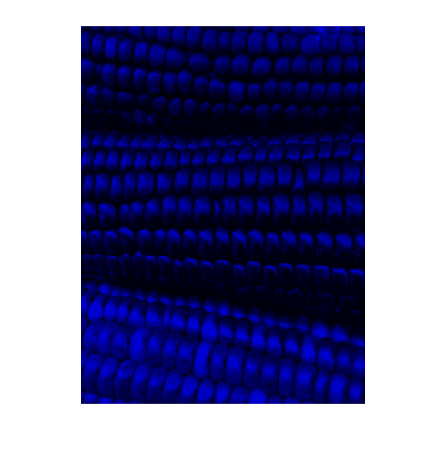

%imwrite(I,b,"blueCorn.png")
imshow(I,b);

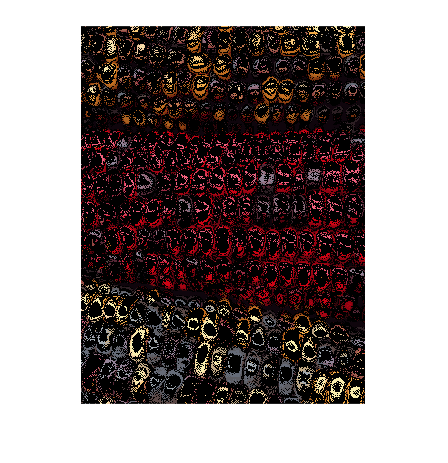


% punto 2.2

r = zeros(256,3);
g = zeros(256,3);
b = zeros(256,3);

r(1:32,1) = map(1:32,1);
g(1:32,2) = map(1:32,2);
b(1:32,3) = map(1:32,3);
imshow(I,r+g+b)

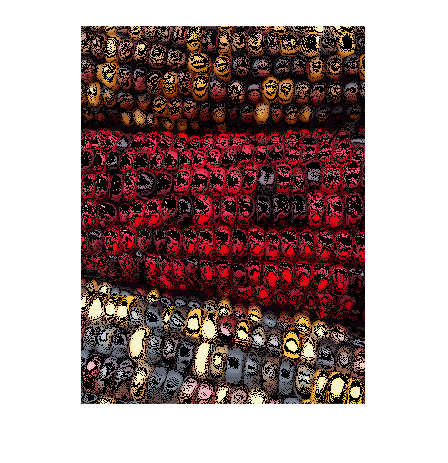

%imwrite(I,r+g+b,"corn32.png")

r(1:64,1) = map(1:64,1);
g(1:64,2) = map(1:64,2);
b(1:64,3) = map(1:64,3);
imshow(I,r+g+b)

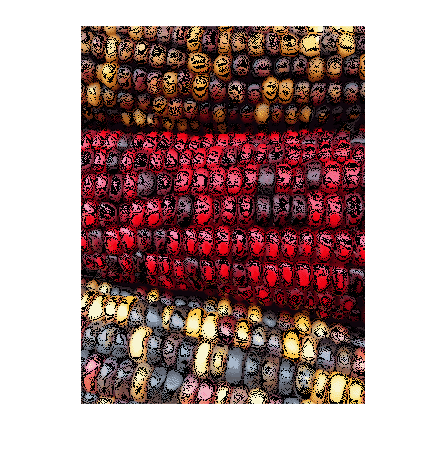

%imwrite(I,r+g+b,"corn64.png")

r(1:80,1) = map(1:80,1);
g(1:80,2) = map(1:80,2);
b(1:80,3) = map(1:80,3);
imshow(I,r+g+b)

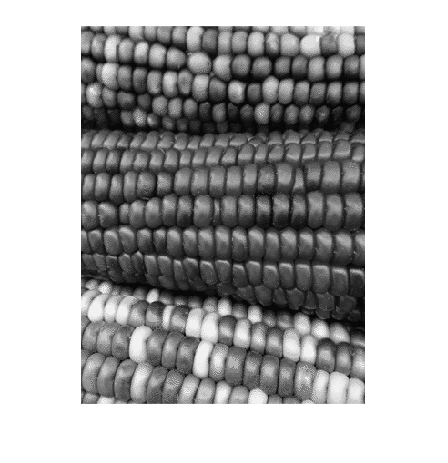

%imwrite(I,r+g+b,"corn80.png")

% punto 2.3
graymap = rgb2gray(map);
imshow(I, graymap)

%imwrite(I,graymap,"cornGrey.png")
% punto 2.4

n32 = zeros(256,3);
n32(1:32,1:3) = map(1:32,1:3);
imshow(I,n32)

whos n32

  Name        Size            Bytes  Class     Attributes

  n32       256x3              6144  double              




n64 = zeros(256,3);
n64(1:64,1:3) = map(1:64,1:3);
imshow(I,n64)

whos n64

  Name        Size            Bytes  Class     Attributes

  n64       256x3              6144  double              



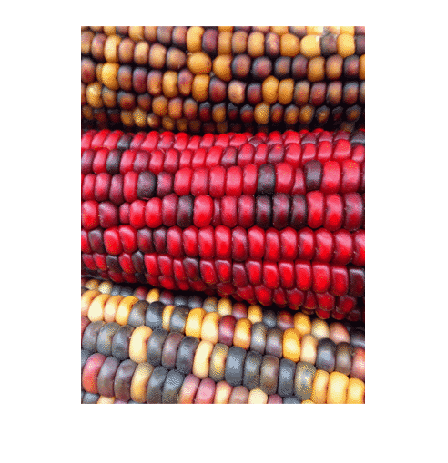


n128 = zeros(256,3);
n128(1:128,1:3) = map(1:128,1:3);
imshow(I,n128)

whos n128

  Name        Size            Bytes  Class     Attributes

  n128      256x3              6144  double              



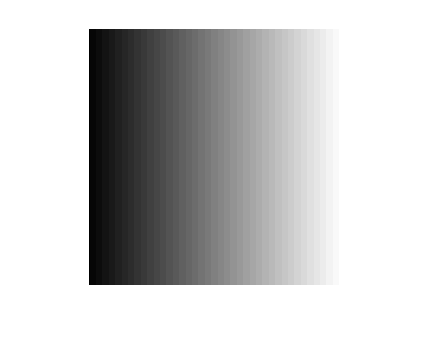

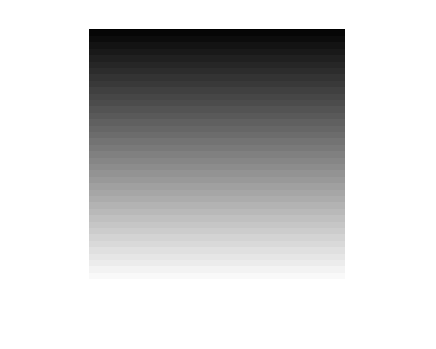

% Punto 3
gris(40)


% Punto 4
%cuadra1 = figura("cuadrado",1); cuadra = figura("cuadrado",0);
%rectan1 = figura("rectangulo",1); rectan = figura("rectangulo",0);
%triang1 = figura("triangulo",1); triang = figura("triangulo",0);
%circul1 = figura("circulo",1);circul = figura("circulo",0);
%todoss1 = figura("todos",1);todoss = figura("todos",0);
figura("cuadrado",1);figura("cuadrado",0);
figura("rectangulo",1);figura("rectangulo",0);
figura("triangulo",1);figura("triangulo",0);
figura("circulo",1);figura("circulo",0);
figura("todos",1);figura("todos",0);

function [] = gris(N) % punto 3
    figure
    J = zeros(256,256);
    for r = 1:256   
        for c = 1:256
            J(r, c) = ceil((c - 1)*N/256);
        end
    end
    imshow(J,[])
    
    figure
    %I = zeros(256,256);
    %for r = 1:256   
    %    for c = 1:256
    %        I(r, c) = ceil((r - 1)*N/256);
    %    end
    %end
    imshow(transpose(J),[])
end


-

% Punto 4
function [] = figura(stringFigura, relleno)
    
    tamanoMatriz = 100;
    switch stringFigura
        case "cuadrado"
            Figura = cuadrado(tamanoMatriz,relleno);
        case "triangulo"
            Figura = triangulo(tamanoMatriz,relleno);
        case "circulo"
            Figura = circulo(tamanoMatriz,relleno);
        case "rectangulo"
            Figura = rectangulo(tamanoMatriz,relleno);
        case "todos"
            n=16; z=zeros(4); V=randperm(n); Figura=zeros(tamanoMatriz*4);
            for i=0:3
              cua=cuadrado(tamanoMatriz,relleno);   zs=z; zs(V(4*i+1))=1; S=kron(zs,cua);
              cir=circulo(tamanoMatriz,relleno);    zc=z; zc(V(4*i+2))=1; C=kron(zc,cir);
              tri=triangulo(tamanoMatriz,relleno);  zt=z; zt(V(4*i+3))=1; T=kron(zt,tri);
              rec=rectangulo(tamanoMatriz,relleno); zr=z; zr(V(4*i+4))=1; R=kron(zr,rec);
              Figura=Figura+S+C+T+R;
            end
        otherwise
            warning('Entrada no valida')
    end
    figure
    imshow(Figura)
end

-

function [Canvas] = cuadrado(tamanoMatriz,rellenar)

    Canvas = zeros(tamanoMatriz);
    tamanoCuadrado = randi([2 tamanoMatriz-1]);

    % Genera un punto inicial dentro de la matriz
    inicio = ceil(rand(1)*(tamanoMatriz - tamanoCuadrado))+1;
    fin = inicio + tamanoCuadrado-1;
    
    if(rellenar)
        Canvas(inicio:fin,inicio:fin) = 1;
    else
        % Horizontal
        Canvas([inicio fin]:fin,[inicio fin]) = 1;
        % Vertical
        Canvas([inicio fin],[inicio fin]:fin) = 1;
    end  
 
end

Funcion para graficar rectangulo

function [Canvas] = rectangulo(tamanoMatriz,rellenar)

    Canvas = zeros(tamanoMatriz);
    tamanoSuperior = randi([4 tamanoMatriz-1]);
    tamanoLados = ceil(tamanoSuperior/2)+1;

    % Genera un punto inicial dentro de la matriz
    inicio = ceil(rand(1)*(tamanoMatriz - tamanoSuperior));

    finVertical = inicio + tamanoSuperior - 1;
    finHorizontal = inicio + tamanoLados - 1;
    
    horizontal = randi([0 1]);

    if(rellenar)
        if horizontal
            Canvas(inicio:finHorizontal,inicio:finVertical) = 1;
        else
            Canvas(inicio:finVertical,inicio:finHorizontal) = 1;
        end
    else
        if horizontal
            Canvas([inicio finVertical]:finHorizontal,[inicio finVertical]) = 1;
            Canvas([inicio finHorizontal],[inicio finHorizontal]:finVertical) = 1;
        else
            Canvas([inicio finHorizontal]:finVertical,[inicio finHorizontal]) = 1;
            Canvas([inicio finVertical],[inicio finVertical]:finHorizontal) = 1;
        end
    end  
    
end

Funcion para graficar triangulo

function [Canvas] = triangulo(tamanoMatriz,rellenar)

    Canvas = zeros(tamanoMatriz);

    tamanoTriangulo = randi([4 (tamanoMatriz-1)]);

    inicio = ceil(rand(1)*(tamanoMatriz - tamanoTriangulo))+1;

    Canvas(inicio,inicio) = 1;
    
    try
        for  i=1:tamanoTriangulo-1
            Canvas(inicio+i,inicio-i:inicio+i) = 1;
        end
        
        if(~rellenar)
            Canvas(inicio+1,inicio) = 0;
            for  i=1:tamanoTriangulo-2
                Canvas(inicio+i,inicio-i+1:inicio+i-1) = 0;
            end
        end
    catch
        Canvas = zeros(tamanoMatriz);
        Canvas(inicio,inicio) = 1;

        for  i=1:tamanoTriangulo-1
            Canvas(inicio+i,inicio:inicio+i) = 1;
        end

        if(~rellenar)
            Canvas(inicio+2,inicio+1) = 0;
            for  i=1:tamanoTriangulo-3
                Canvas(inicio+2+i-1,inicio+1:inicio+i) = 0;
            end
        end
    end
end

-

function [Canvas] = circulo(tamanoMatriz,rellenar)
    Canvas = zeros(tamanoMatriz);
    radio = randi([2 (tamanoMatriz/2)]);
    
    centro_h = randi([radio tamanoMatriz-radio]);
    centro_k = randi([radio tamanoMatriz-radio]);

    %theta = linspace(0,2*pi);
    theta = 0:pi/10000:2*pi;
    X = centro_h + (radio).*cos(theta);
    Y = centro_k + (radio).*sin(theta);

    for i=1:length(X)
        Canvas(ceil(X(i)), ceil(Y(i))) = 1;
    end
    
    if(rellenar)
        radioAux = radio;
        while(radioAux ~= 0)
            radioAux = radioAux - 1;
            X = centro_h + (radioAux).*cos(theta);
            Y = centro_k + (radioAux).*sin(theta);
            for i=1:length(X)
                Canvas(ceil(X(i)), ceil(Y(i))) = 1;
            end
        end
    end
end